clc; 
clear all;
close all;
path(pathdef);

T1 = readtable('data_part_1.csv', 'ReadVariableNames',true, 'VariableNamingRule','preserve');
T2 = readtable('data_part_2.csv', 'ReadVariableNames',true, 'VariableNamingRule','preserve');
commonColumns = intersect(T1.Properties.VariableNames, T2.Properties.VariableNames, 'stable');

T_full = [T1(:, commonColumns); T2(:, commonColumns)];
T_full(:, 1) = [] % remove index col

T_full = 13295×1741 table
    Anthocyanin content (μg/cm²)    Boron content (mg/cm²)    C content (mg/cm²)    Ca content (mg/cm²)    Carotenoid content (μg/cm²)    Cellulose (mg/cm²)    Chl content (μg/cm²)    Copper content (mg/cm²)    EWT (mg/cm²)    Fiber (mg/cm²)    LAI (m²/m²)    LMA (g/m²)    Lignin (mg/cm²)    Magnesium content (mg/cm²)    Manganese content (mg/cm²)    N content (mg/cm²)    NSC (mg/cm²)    Phosphorus content (mg/cm²)    Potassium content (mg/cm²)    Sulfur content (mg/cm²)       400          401          402          403          404          <s


T_traits = T_full(:, 1:20)

T_traits = 13295×20 table
    Anthocyanin content (μg/cm²)    Boron content (mg/cm²)    C content (mg/cm²)    Ca content (mg/cm²)    Carotenoid content (μg/cm²)    Cellulose (mg/cm²)    Chl content (μg/cm²)    Copper content (mg/cm²)    EWT (mg/cm²)    Fiber (mg/cm²)    LAI (m²/m²)    LMA (g/m²)    Lignin (mg/cm²)    Magnesium content (mg/cm²)    Manganese content (mg/cm²)    N content (mg/cm²)    NSC (mg/cm²)    Phosphorus content (mg/cm²)    Potassium content (mg/cm²)    Sulfur content (mg/cm²)
    ____________________________    ______________________    __________________    _______________

T_spectra = T_full(:, 21:end)

T_spectra = 13295×1721 table
       400          401          402          403          404          405          406          407          408          409          410          411          412          413          414          415          416          417          418          419          420          421          422          423          424          425          426          427          428          429         430          431          

## Visualization

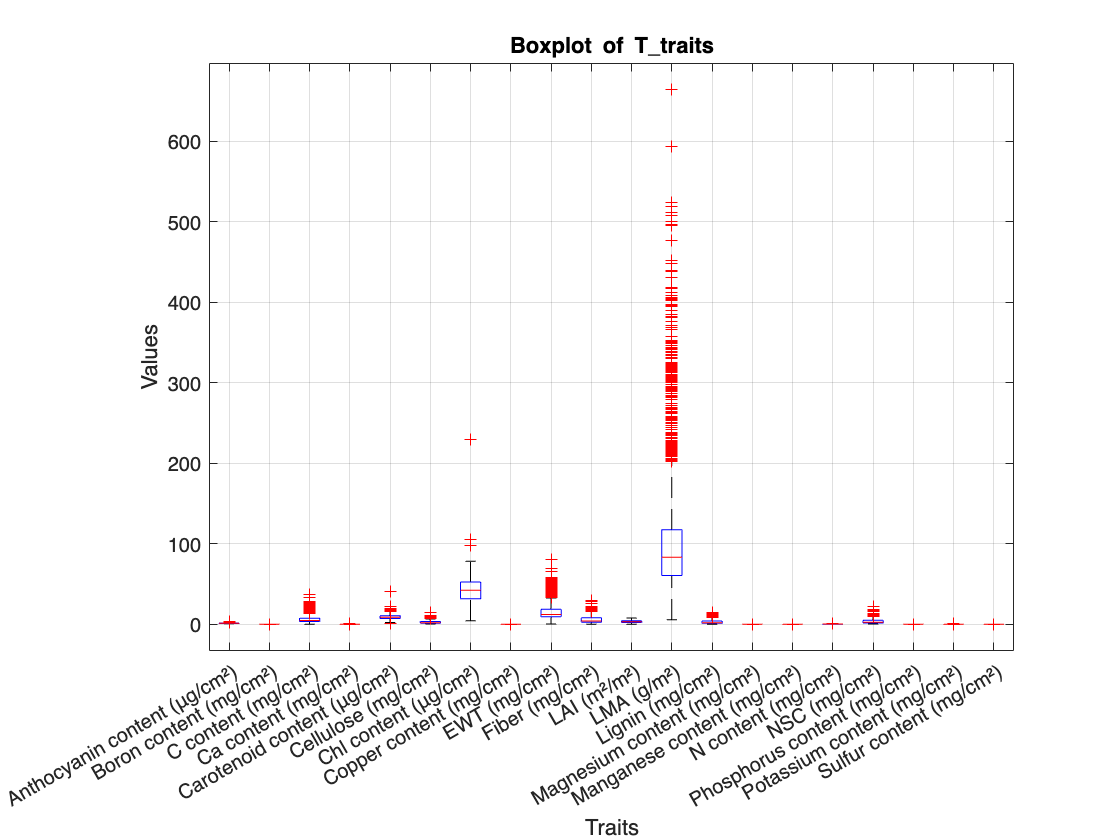

% DATA PART 1&2
columnNames1 = T1.Properties.VariableNames;
columnNames2 = T2.Properties.VariableNames;

size1 = size(T1);
size2 = size(T2);
sizeText1 = sprintf('Size: %d rows, %d cols', size1(1), size1(2));
sizeText2 = sprintf('Size: %d rows, %d cols', size2(1), size2(2));

f = figure('Position', [300 300 600 450], 'Name', 'Column Names and Sizes', 'NumberTitle', 'off');

% uicontrol('Style', 'listbox', 'Position', [50 70 200 280], 'String', columnNames1, 'Parent', f);
% uicontrol('Style', 'text', 'Position', [50 360 200 20], 'String', 'Table 1 Column Names', 'Parent', f, 'HorizontalAlignment', 'center');
% uicontrol('Style', 'text', 'Position', [50 40 200 20], 'String', sizeText1, 'Parent', f, 'HorizontalAlignment', 'center');
% 
% uicontrol('Style', 'listbox', 'Position', [350 70 200 280], 'String', columnNames2, 'Parent', f);
% uicontrol('Style', 'text', 'Position', [350 360 200 20], 'String', 'Table 2 Column Names', 'Parent', f, 'HorizontalAlignment', 'center');
% uicontrol('Style', 'text', 'Position', [350 40 200 20], 'String', sizeText2, 'Parent', f, 'HorizontalAlignment', 'center');

% Boxplot
T_traits_matrix = table2array(T_traits); 
varNames = T_traits.Properties.VariableNames;

figure;
boxplot(T_traits_matrix, 'Labels', varNames);
title('Boxplot of T\_traits');
xlabel('Traits');
ylabel('Values');
grid on;

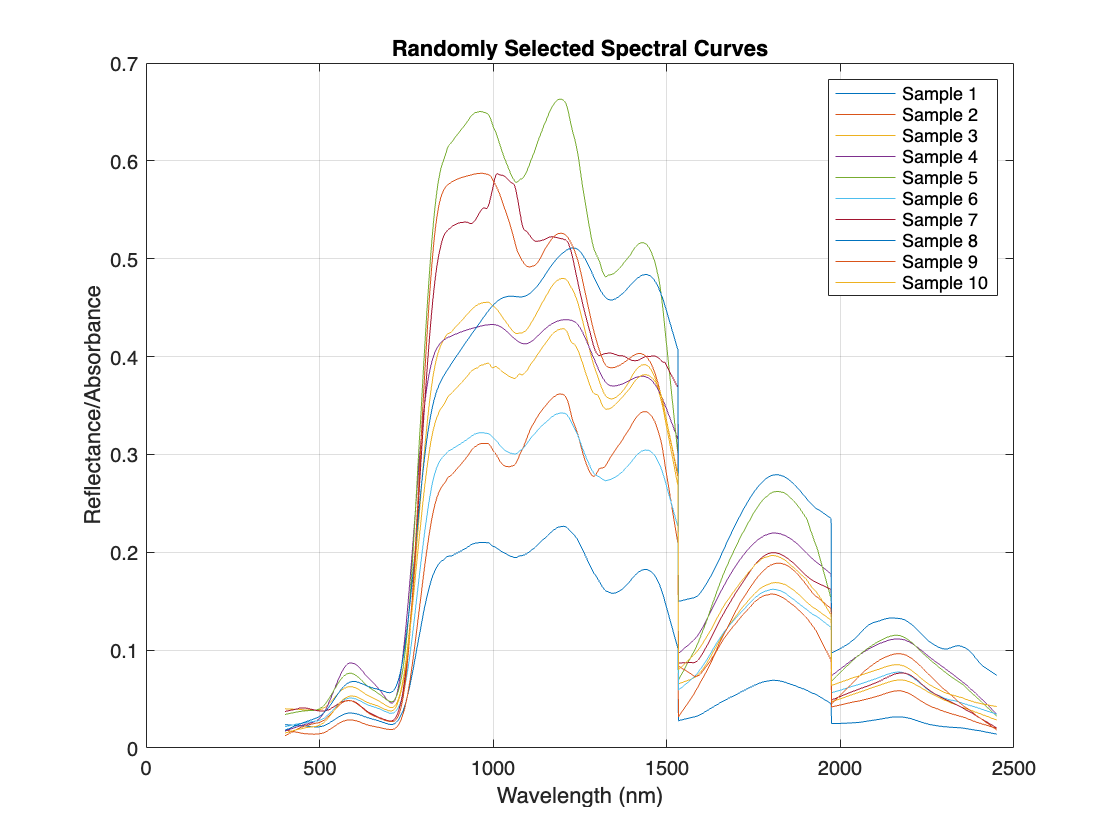


% Spectral Curves
T_spectra_matrix = table2array(T_spectra);
num_samples = size(T_spectra_matrix, 1);

random_indices = randperm(num_samples, 10);
selected_samples = T_spectra_matrix(random_indices, :);

wavelengths = linspace(400, 2450, size(T_spectra_matrix, 2));

figure;
plot(wavelengths, selected_samples');
title('Randomly Selected Spectral Curves');
xlabel('Wavelength (nm)');
ylabel('Reflectance/Absorbance');
grid on;
legend('Sample 1', 'Sample 2', 'Sample 3', 'Sample 4', 'Sample 5', ...
       'Sample 6', 'Sample 7', 'Sample 8', 'Sample 9', 'Sample 10');

% Summary
varNames = T_traits.Properties.VariableNames;
xNames = varNames(1:end-1)

xNames = 1×19 cell array
    {'Anthocyanin content (μg/cm²)'}    {'Boron content (mg/cm²)'}    {'C content (mg/cm²)'}    {'Ca content (mg/cm²)'}    {'Carotenoid content (μg/cm²)'}    {'Cellulose (mg/cm²)'}    {'Chl content (μg/cm²)'}    {'Copper content (mg/cm²)'}    {'EWT (mg/cm²)'}    {'Fiber (mg/cm²)'}    {'LAI (m²/m²)'}    {'LMA (g/m²)'}    {'Lignin (mg/cm²)'}    {'Magnesium content (mg/cm²)'}    {'Manganese content (mg/cm²)'}    {'N content (mg/cm²)'}    {'NSC (mg/cm²)'}    {'Phosphorus content (mg/cm²)'}    {'Potassium content (mg/cm²)'}



meanVals = [];
minVals = [];
maxVals = [];
numMissing = [];

for i = 1:numel(varNames)
    meanVals = [meanVals; mean(T_traits.(varNames{i}), 'omitnan')];
    minVals = [minVals; min(T_traits.(varNames{i}))];
    maxVals = [maxVals; max(T_traits.(varNames{i}))];
    numMissing = [numMissing; sum(ismissing(T_traits.(varNames{i})))];
end

summaryTable = table(varNames', meanVals, minVals, maxVals, numMissing, ...
    'VariableNames', {'Variable', 'Mean', 'Min', 'Max', 'NumMissing'});

disp(summaryTable);

                Variable                   Mean          Min           Max        NumMissing
    ________________________________    __________    __________    __________    __________

    {'Anthocyanin content (μg/cm²)'}        1.2652       0.56104        2.9811      12597   
    {'Boron content (mg/cm²)'      }    0.00041765      7.76e-06     0.0023379       9266   
    {'C content (mg/cm²)'          }        6.6214       0.10275        37.292       7406   
    {'Ca content (mg/cm²)'         }        0.1156    0.00069226       0.98872       9375   
    {'Carotenoid content (μg/cm²)' }        9.1649        1.1826        40.443       8653   
    {'Cellulose (mg/cm²)'          }        2.6184       0.34988        15.223       8754   
    {'Chl content (μg/cm²)'        }        42.057        4.4483         229.5       

## Choosing single trait

% leaving only single trait
targetIdx = 11 % 12 for "LMA", 11 for "LAI"

targetIdx = 11

targetName = string(T_full.Properties.VariableNames(targetIdx))

targetName = "LAI (m²/m²)"

T_single = T_full(:,[targetIdx 21:end]);
T_single = rmmissing(T_single)

T_single = 4042×1722 table
    LAI (m²/m²)      400          401          402          403          404          405          406         407          408          409          410          411          412          413          414          415          416          417         418          419          420          421          422          423          424         425          426          427          428          429          430          

varNames = T_single.Properties.VariableNames;
xNames = varNames(2:end)

xNames = 1×1721 cell array
    {'400'}    {'401'}    {'402'}    {'403'}    {'404'}    {'405'}    {'406'}    {'407'}    {'408'}    {'409'}    {'410'}    {'411'}    {'412'}    {'413'}    {'414'}    {'415'}    {'416'}    {'417'}    {'418'}    {'419'}    {'420'}    {'421'}    {'422'}    {'423'}    {'424'}    {'425'}    {'426'}    {'427'}    {'428'}    {'429'}    {'430'}    {'431'}    {'432'}    {'433'}    {'434'}    {'435'}    {'436'}    {'437'}    {'438'}    {'439'}    {'440'}    {'441'}    {'442'}    {'443'}    {'444'}    {'445'}    {'446'}    {'447'}    {'448'}    {'449'}    {'450'}    {'451'}    {'452'}    {'453'}    {'454'}    {'455'}    {'456'}    {'457'}    {'458'}    {'459'}    {'460'}    {'461'}    {'462'}    {'463'}    {'464'}    {'465'}    {'466'}    {'467'}    {'468'}    {'469'}    {'470'}    {'471'}    {'472'}    {'473'}    {'474'}    {'475'}    {'476'}    {'477'}    {'478'}    {'479'}    {'480'}    {'481'}    {'482'}    {'483'}    {'484'}    {'485'}    {'486'}    {'487'}    {

## Data division

% Into predictor variables and predicted variable
model(1).X0 = T_single{:,2:end};
model(1).Y0 = T_single{:,1};
model(1).varNames = xNames;

% Making division between calibration and validation
nobs    = length(model(1).Y0);

% We save 30% of the data for validation
part    = cvpartition(nobs, 'HoldOut', 0.3);
idxCal  = training(part);
idxTest  = test(part);

% X-side variables
% Center the mean tßo 0 and scale to the standard deviation of 1 the
% calibration set
[model(1).XCal, model(1).mu, model(1).sigma] = zscore(model(1).X0(idxCal, :));

% Apply the calibration center and standard deviation to the validation
% partition
model(1).XTest   = normalize(model(1).X0(idxTest,:), 'Center', model(1).mu, 'Scale', model(1).sigma);

% Y-side variables - We center it; a difference in the model is that the
% intercepts are not statistically significant if we center it
model(1).YCal   = model(1).Y0(idxCal) - mean(model(1).Y0(idxCal));
model(1).YTest  = model(1).Y0(idxTest) - mean(model(1).Y0(idxCal));

## Cross-validation

- we do not use the scaled data matrix at this point because we will scale in each cross-validation iteration.

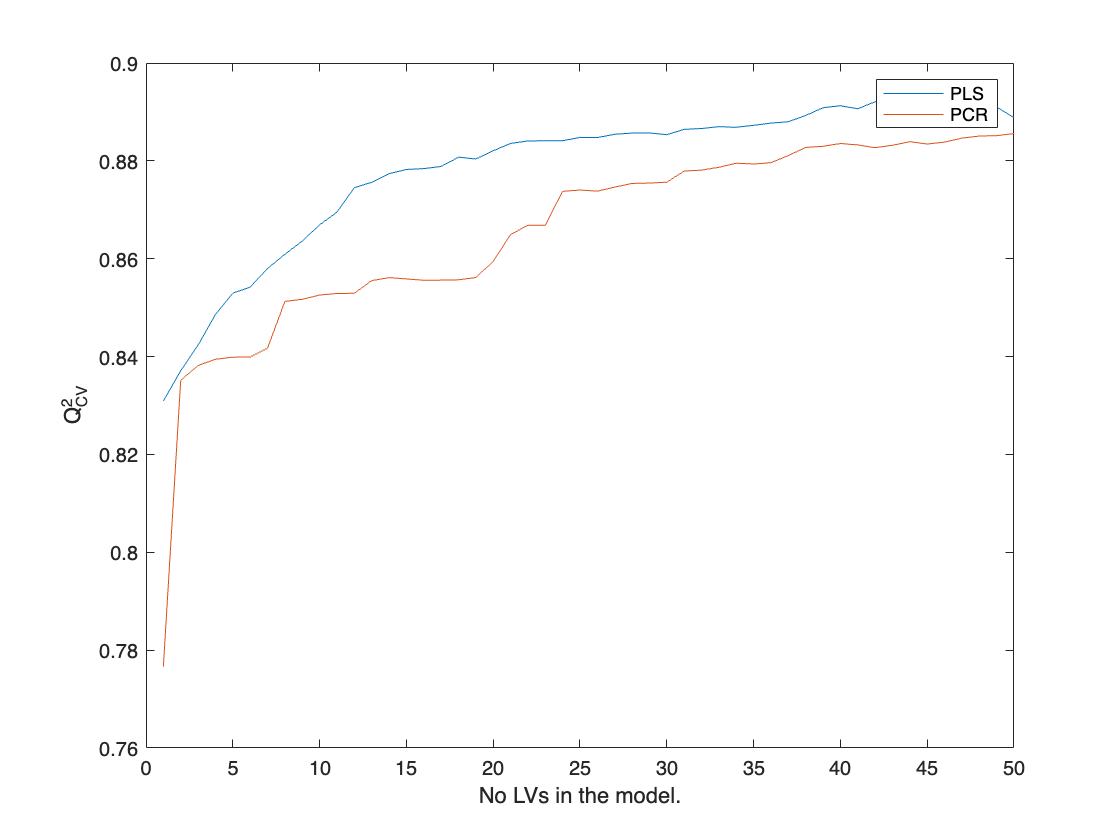


X = model(1).X0(idxCal, :);
Y = model(1).Y0(idxCal);

k = 5;

cv = cvpartition(size(Y, 1), 'KFold', k);


for i = 1:cv.NumTestSets

    trainIdx = training(cv, i);
    testIdx  = test(cv, i);

    X_cal  = X(trainIdx, :);
    Y_cal = Y(trainIdx, :);

    X_val  = X(testIdx, :);
    Y_val  = Y(testIdx, :);

    % Center and Scale
    [XCal, mu, sigma] = zscore(X_cal);
    XVal = normalize(X_val, "center", mu, "scale", sigma);
    YCal = Y_cal - mean(Y_cal);
    YVal = Y_val - mean(Y_cal);

    [P, T, latent] = pca(XCal, 'Centered', false, 'Economy', false);


    TSS = sum((YCal - mean(YCal)).^2);

    [rows, ~] = size(XVal);

    for j = 1:50

        bPCR = [];
        bPCR            = P(:,1:j) * regress(YCal, T(:,1:j));
        bPCR            = [mean(YCal) - mean(XCal) * bPCR; bPCR];
        YPredPCR        = [ones(rows,1) XVal] * bPCR;
        PRESSPCR(i,j)   = sum((YPredPCR - YVal).^2);
        RMSEPCR(i,j)    = rmse(YPredPCR, YVal);
        Q2PCR(i,j)      = 1 - PRESSPCR(i,j)/TSS;

        [~, ~, ~, ~, bPLS] = plsregress(XCal, YCal, j);
        YPredPLS        = [ones(rows,1) XVal] * bPLS;
        PRESSPLS(i,j)   = sum((YPredPLS - YVal).^2);
        Q2PLS(i,j)      = 1 - PRESSPLS(i,j)/TSS;
        RMSEPLS(i,j)    = rmse(YPredPLS, YVal);

    end

end


Q2_CV_PCR = mean(Q2PCR);
Q2_CV_PLS = mean(Q2PLS);

PRESS_CV_PLS = mean(PRESSPLS);
PRESS_CV_PCR = mean(PRESSPCR);

RMSE_CV_PLS = mean(RMSEPLS);
RMSE_CV_PCR = mean(RMSEPCR);

figure;
plot(Q2_CV_PLS);
hold on;
plot(Q2_CV_PCR);
xlabel("No LVs in the model.")
ylabel("Q^2_{CV}")
legend(["PLS"; "PCR"])

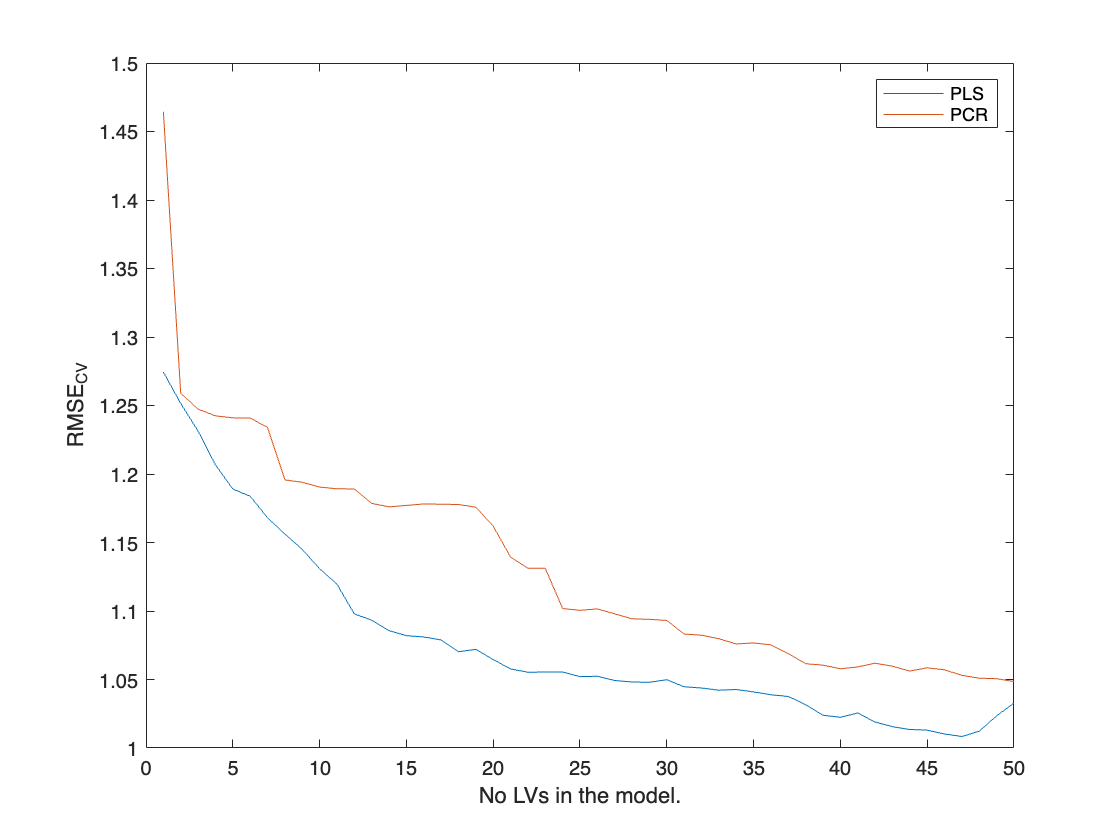


figure;
plot(RMSE_CV_PLS);
hold on;
plot(RMSE_CV_PCR);
xlabel("No LVs in the model.")
ylabel("RMSE_{CV}")
legend(["PLS"; "PCR"]);

## Decision: Number of LVs

noPCsPLS = 10;

## Explained variance in X and Y

[Pe, Te, ~, ~, var] = pca(model(1).XCal, 'Economy', false);

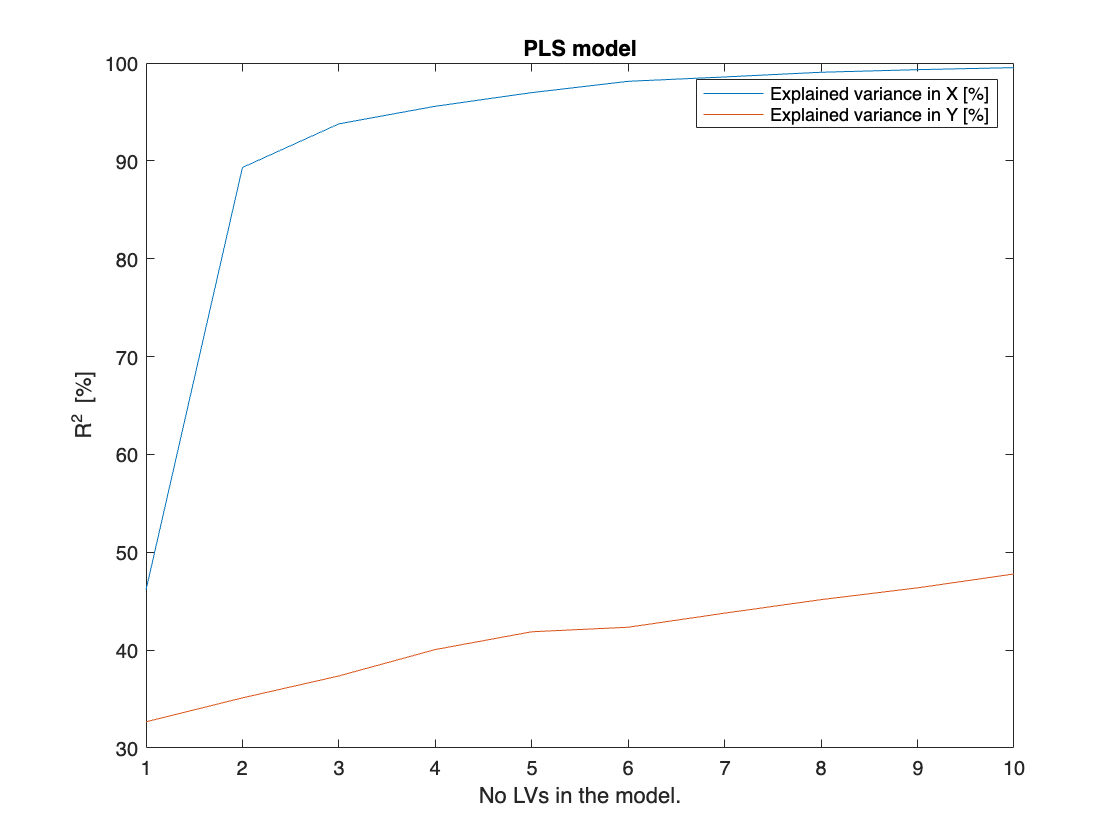


R2_X_PCR    = cumsum(var);
[rows, ~]   = size(model(1).XCal);

TSS = sum((model(1).YCal - mean(model(1).YCal)).^2);

for j = 1:50
    bPCR = [];
    bPCR            = P(:,1:j) * regress(model(1).YCal, Te(:,1:j));
    bPCR            = [mean(model(1).YCal) - mean(model(1).XCal) * bPCR; bPCR];
    YEstPCR         = [ones(rows,1) model(1).XCal] * bPCR;
    RSS             = sum((model(1).YCal - YEstPCR).^2);
    R2_Y_PCR(j)     = (1 - RSS/TSS)*100; 
end

[~, ~, ~, ~, bPLS, varPLS] = plsregress(model(1).XCal, model(1).YCal, noPCsPLS);

R2_X_PLS = cumsum(varPLS(1,:));
R2_Y_PLS = cumsum(varPLS(2,:));


figure;
plot(R2_X_PLS*100);
hold on;
plot(R2_Y_PLS*100);
title("PLS model");
xlabel("No LVs in the model.");
ylabel("R^2 [%]");
legend(["Explained variance in X [%]", "Explained variance in Y [%]"]);

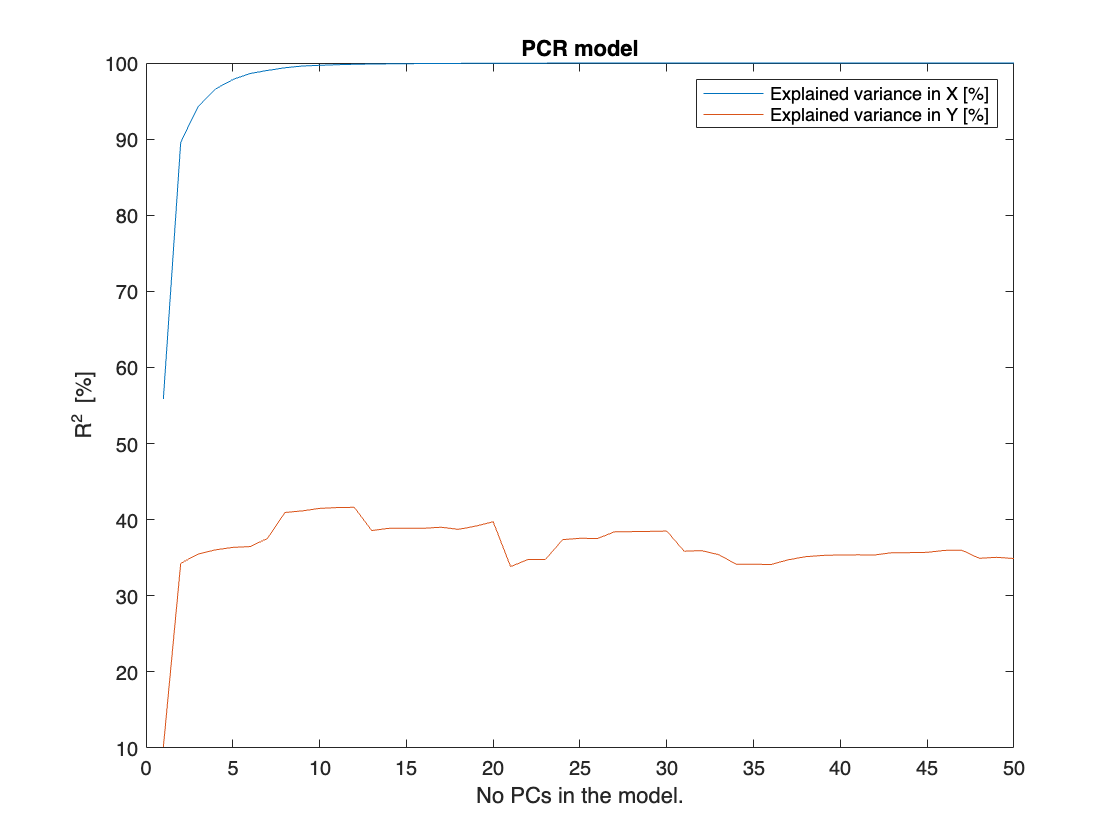


figure;
plot(R2_X_PCR(1:50));
hold on;
plot(R2_Y_PCR(1:50));
ylabel("R^2 [%]");
title("PCR model");
xlabel("No PCs in the model.")
legend(["Explained variance in X [%]", "Explained variance in Y [%]"]);

## Triplot

[model(1).YCal, muY, sigmaY] = zscore(model(1).YCal);
model(1).YTest               = normalize(model(1).YTest, 'center', muY, 'scale', sigmaY);

[P, Q, T, U, bPLS, varPLS, mse, stats] = plsregress(model(1).XCal, model(1).YCal, noPCsPLS);



% figure;
% b = biplot([P(:, 1:2); Q(:, 1:2)], 'Scores', T(:, 1:2), 'VarLabels', varNames);
% xlabel("Latent Variable 1");
% ylabel("Latent Variable 2");

% Find all the line objects in the biplot
% lines = findobj(b, 'Type', 'line');

% Loop through the line objects and find the loading vectors (which originate from the origin)
% origin = [0 0];  % Define the origin
% loadingLines = [];

% for i = 1:length(lines)
%     % Get X and Y data for the current line
%     xData = get(lines(i), 'XData');
%     yData = get(lines(i), 'YData');
% 
%     % Check if the line starts at the origin (or very close to it)
%     if isequal(round([xData(1), yData(1)], 10), origin)
%         loadingLines = [loadingLines, lines(i)];  % Add this line to the loadingLines array
%     end
% end

% Change the color of the last coefficient (loading) line
% set(loadingLines(end), 'Color', 'r', 'LineWidth', 2);  % Change the color to red and make it thicker

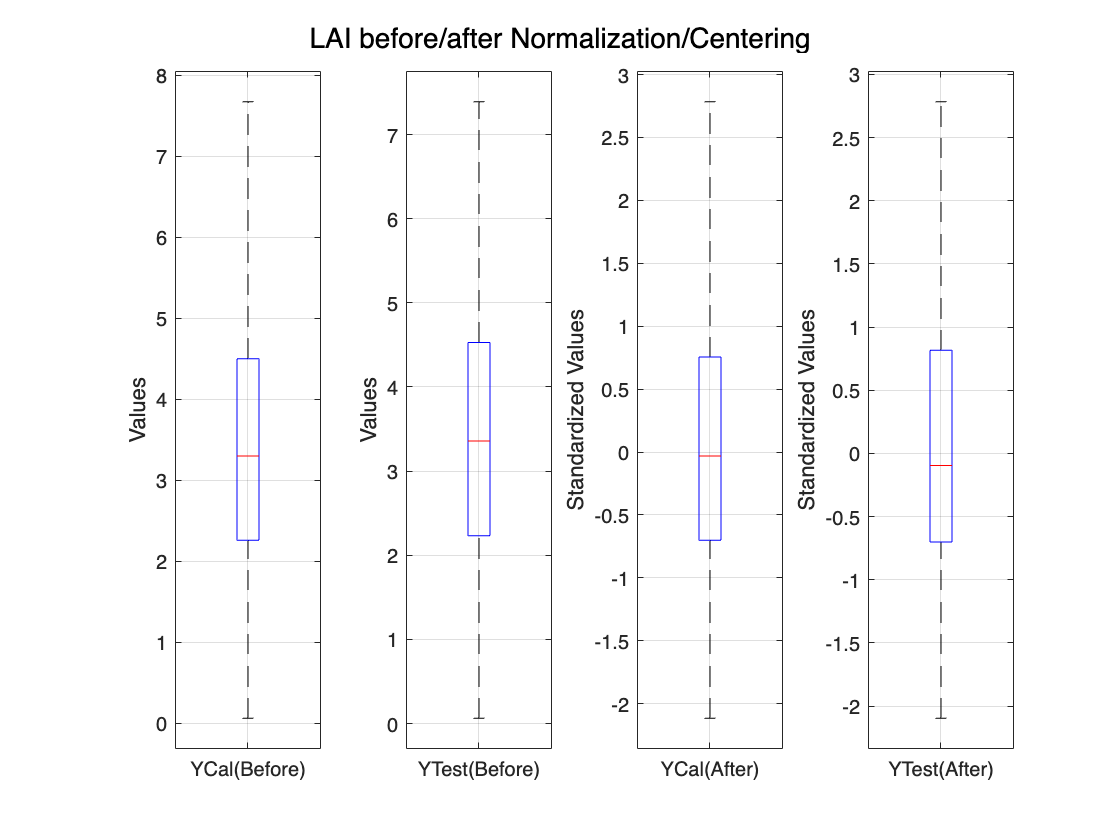

% before/after Normalization/Centering
figure;

sgtitle('LAI before/after Normalization/Centering', 'FontSize', 14);

subplot(1, 4, 1); 
boxplot(Y_cal, 'Labels', 'YCal(Before)');
ylabel('Values');
grid on;

subplot(1, 4, 2); 
boxplot(Y_val, 'Labels', 'YTest(Before)');
ylabel('Values');
grid on;

subplot(1, 4, 3); 
boxplot(model(1).YCal, 'Labels', 'YCal(After)');
ylabel('Standardized Values');
grid on;

subplot(1, 4, 4); 
boxplot(model(1).YTest, 'Labels','YTest(After)');
ylabel('Standardized Values');
grid on;

## VIP

W0 = stats.W ./ sqrt(sum(stats.W.^2,1));
p              = size(P, 1);
sumSq          = sum(T.^2,1).*sum(Q.^2,1);
vipScore       = sqrt(p* sum(sumSq.*(W0.^2),2) ./ sum(sumSq,2));
indVIP         = find(vipScore >= 1);
figure;
% scatter(1:length(vipScore),vipScore,'o', 'filled')
doubleVarNames = str2double(model(1).varNames)

doubleVarNames =    400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449


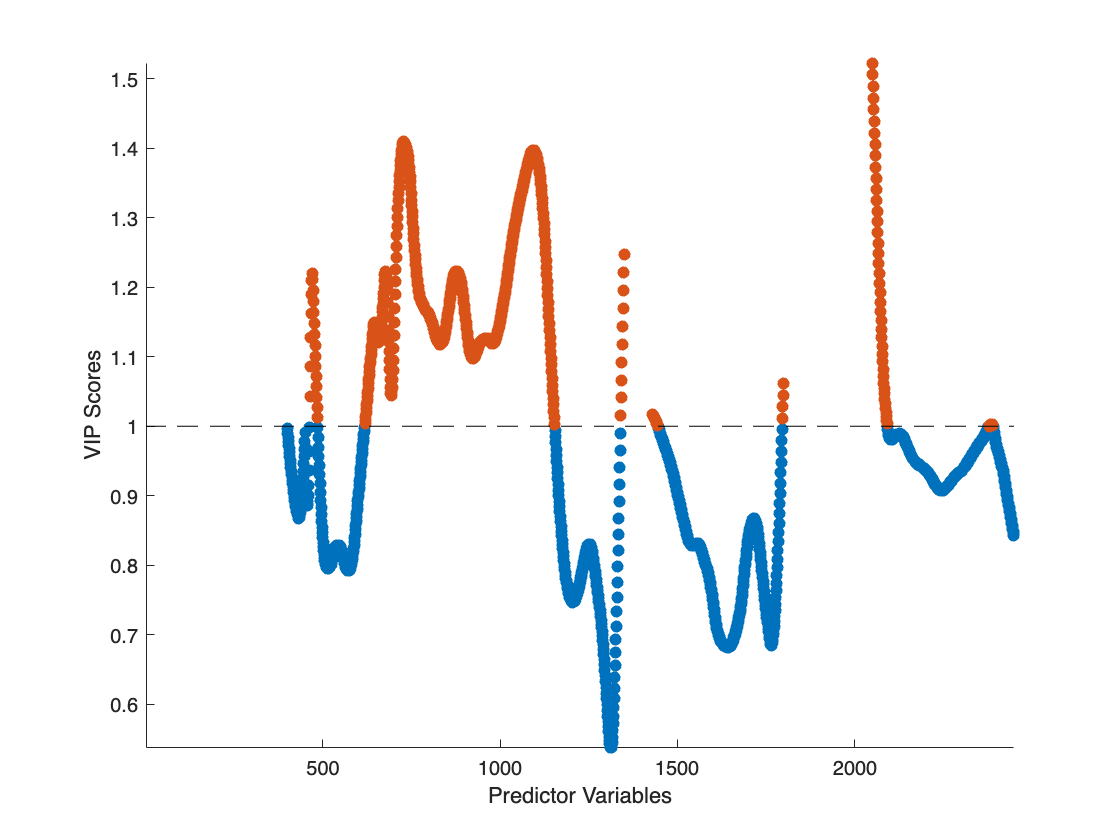

scatter(doubleVarNames,vipScore,'o', 'filled')
hold on
scatter(doubleVarNames(indVIP),vipScore(indVIP),'o', 'filled')
plot([1 doubleVarNames(end)],[1 1],'--k')
hold off
axis tight
xlabel('Predictor Variables')
ylabel('VIP Scores')

% xticklabels(str2double(model(1).varNames));

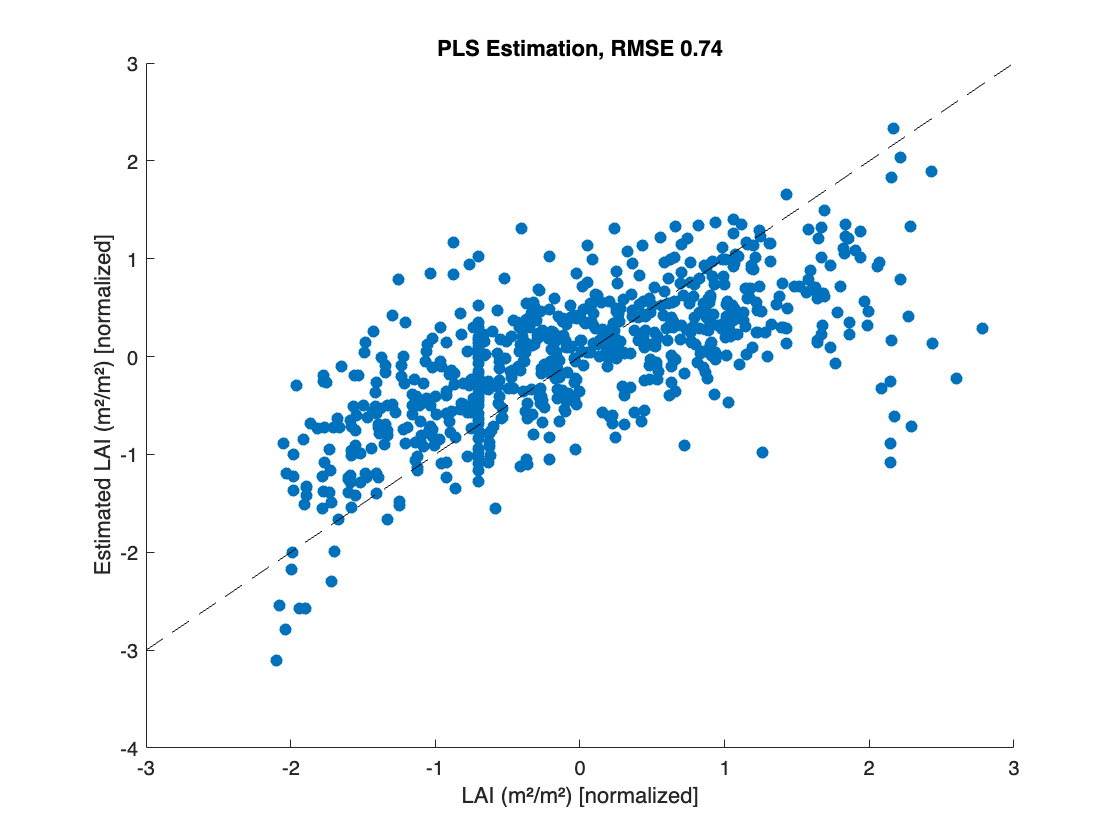

[row, col] = size(model(1).XTest);
YTestPred  = [ones(row, 1) model(1).XTest] * bPLS;
figure;
scatter(model(1).YTest, YTestPred, 'filled');
hold on
plot([-3 3],[-3 3],'--k')
hold off
xlabel(sprintf("%s [normalized]", targetName));
ylabel(sprintf("Estimated %s [normalized]", targetName));
title(sprintf("PLS Estimation, RMSE %.2f", rmse(YTestPred, model(1).YTest)));

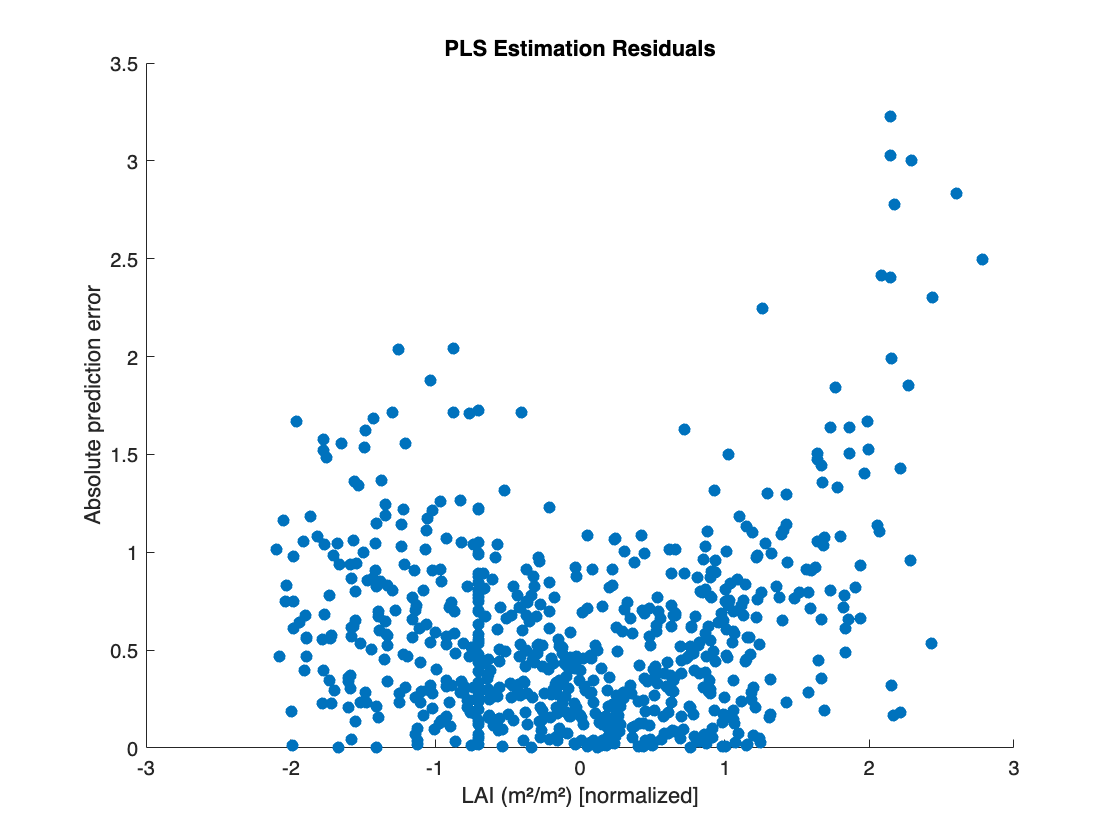

% resid
resid = abs(model(1).YTest - YTestPred);

figure;
scatter(model(1).YTest, resid, 'filled');
xlabel(sprintf("%s [normalized]", targetName));
ylabel("Absolute prediction error");
title("PLS Estimation Residuals");

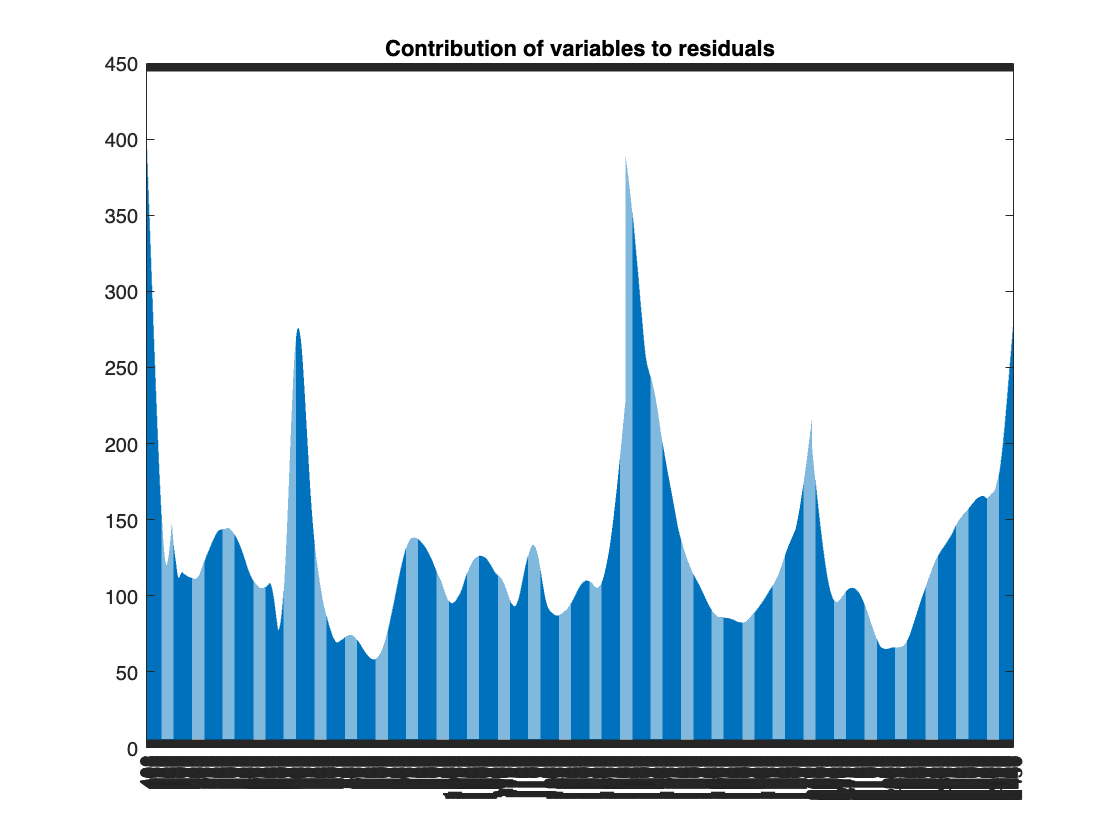

figure; 
bar(model(1).varNames, sum(abs(stats.Xresiduals)));
title("Contribution of variables to residuals");

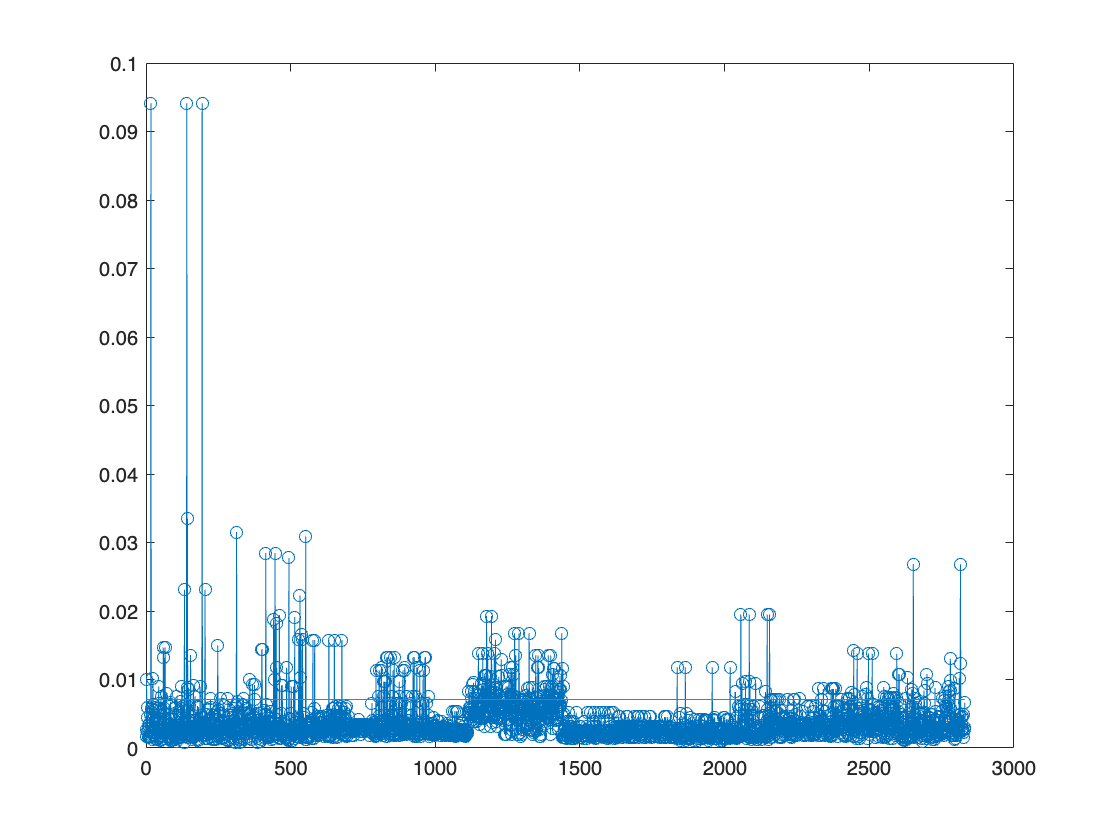

[lev, levLimit] = leveragex(T);

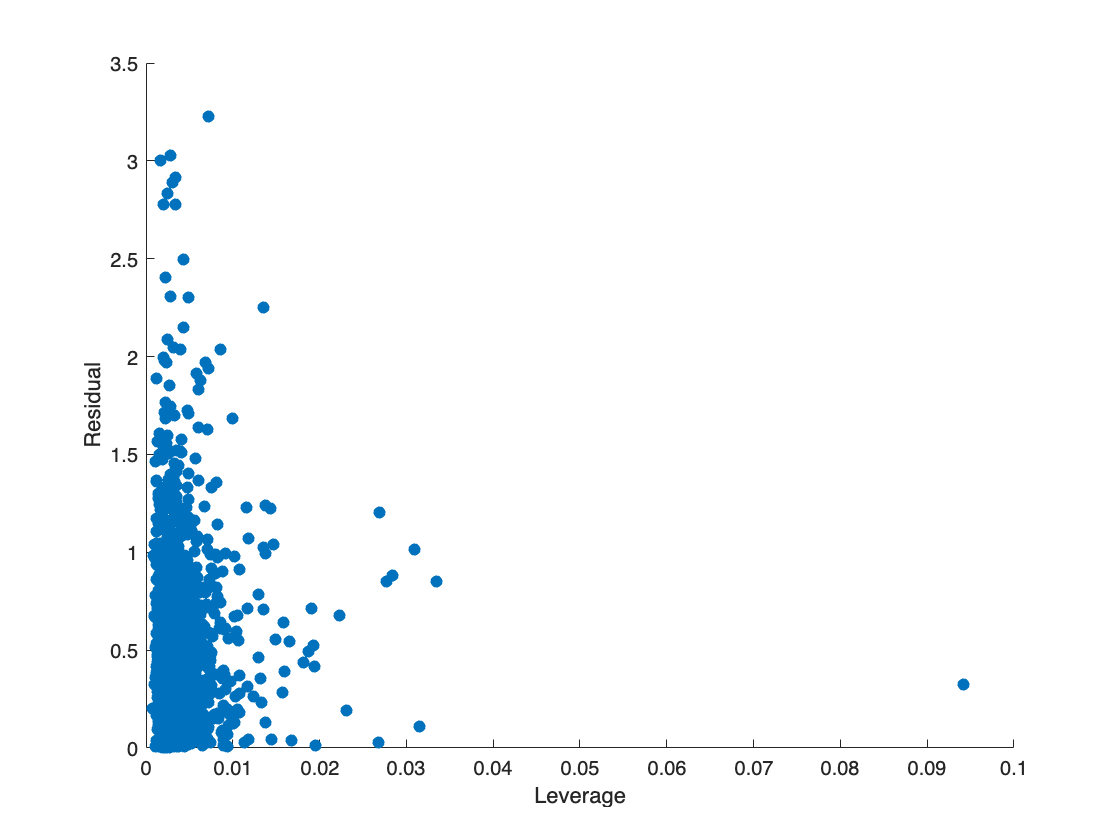


figure;
scatter(lev, abs(stats.Yresiduals), 'filled');
xlabel("Leverage");
ylabel("Residual");


indLeverageFiltered         = find(lev <= 0.02 | abs(stats.Yresiduals) <= 1.5);

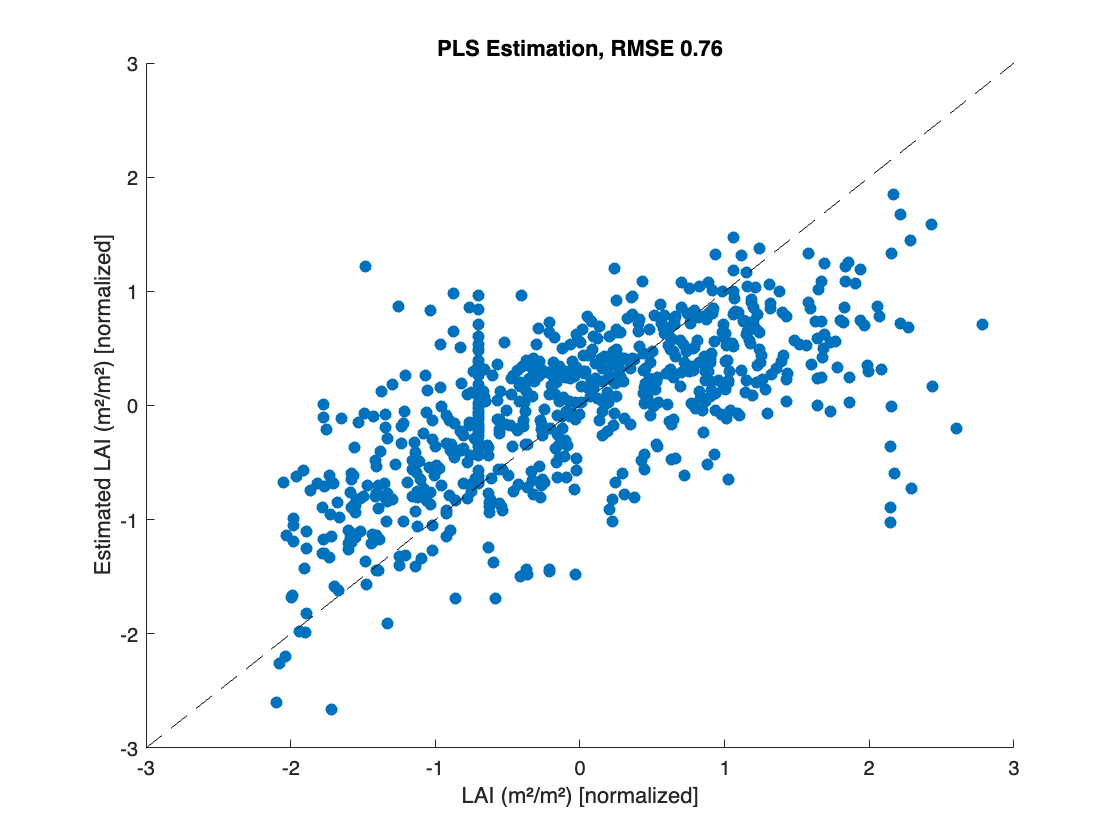

% predict with filtered VIP
[P, Q, T, U, bPLS, varPLS, mse, stats] = plsregress(model(1).XCal(indLeverageFiltered, indVIP), model(1).YCal(indLeverageFiltered, :), noPCsPLS);

[row, col] = size(model(1).XTest(:, indVIP));
YTestPred  = [ones(row, 1) model(1).XTest(:, indVIP)] * bPLS;
figure;
scatter(model(1).YTest, YTestPred, 'filled');
hold on
plot([-3 3],[-3 3],'--k')
hold off
xlabel(sprintf("%s [normalized]", targetName));
ylabel(sprintf("Estimated %s [normalized]", targetName));
title(sprintf("PLS Estimation, RMSE %.2f", rmse(YTestPred, model(1).YTest))) ;

## KPLS for non-linearity

currentFile     = matlab.desktop.editor.getActiveFilename;
[pathstr, ~, ~] = fileparts(currentFile);
paths           = fullfile(pathstr, 'pls-toolbox');
addpath(paths)

% modelPls.initialParam = [1, 1, 1, 1, 1, 1];
modelPls.initialParam = [1,1];
modelPls.nsamp        = 1;
modelPls.learnRate    = 0.2;
modelPls.regrType     = 2; % 1 to be used in classification, 2 for regression, 3 PCR
modelPls.dim          = noPCsPLS; % 2 iver
modelPls.iter         = 500;
modelPls.center       = 1;
modelPls.params       = exp(modelPls.initialParam);
modelPls.plot         = 1;
modelPls.sp           = 0.5;
modelPls.kernelType   = "cauchy";
modelPls.classification = 0; % put = 1 if you are using classification
modelPls.momentum     = 1; % use 1 for classification / 1 works better with few parameters, 2 works better with many parameters
modelPls.family       = 0; % Uses a family of kernels needs 10 parametera -1 for individual variable parameters
modelPls.redPredict   = 0;

modelPls.X = model(1).XCal(indLeverageFiltered, indVIP);
modelPls.Y = model(1).YCal(indLeverageFiltered, :);
modelPls.Xtest = model(1).XTest(:, indVIP);
modelPls.Ytest = model(1).YTest;
modelPls               = predict(modelPls);
modelPls.initialParams = modelPls.params;
modelPls.initialError  = rmse(modelPls.ypred, modelPls.Ytest);

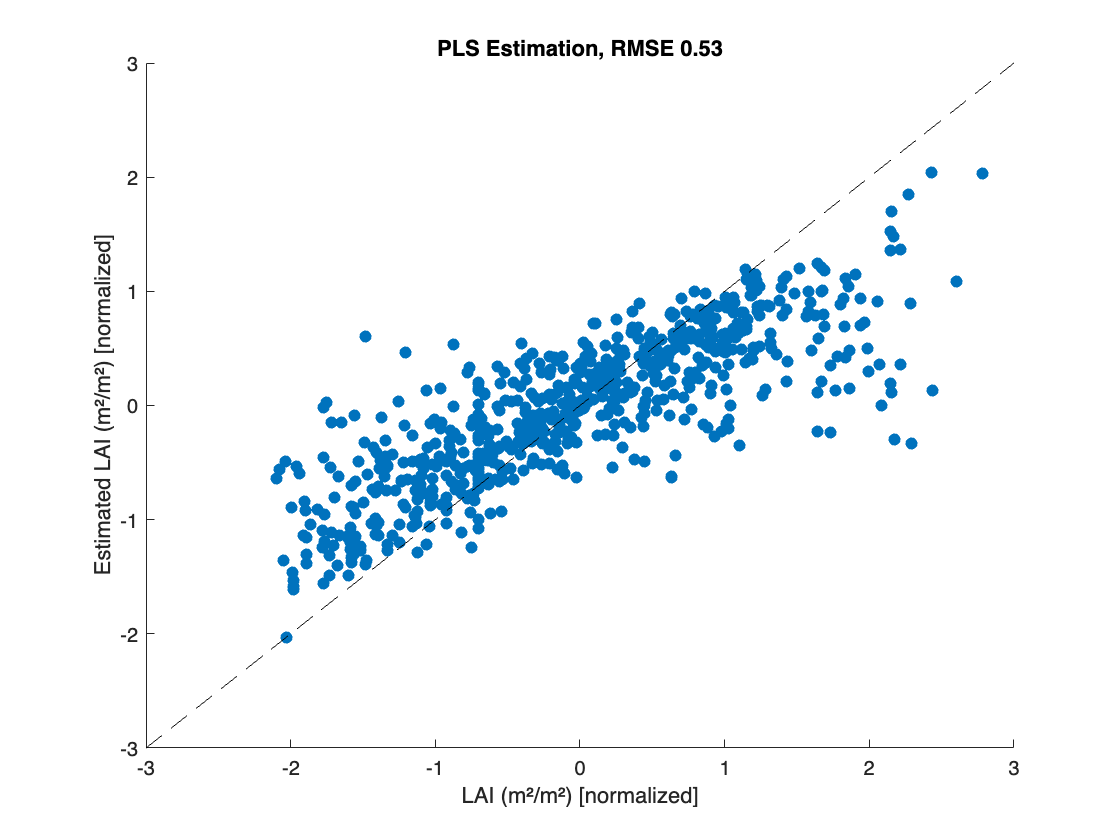

% visualizing kpls
figure;
scatter(model(1).YTest, modelPls.ypred, 'filled');
hold on
plot([-3 3],[-3 3],'--k')
hold off
xlabel(sprintf("%s [normalized]", targetName));
ylabel(sprintf("Estimated %s [normalized]", targetName));
title(sprintf("PLS Estimation, RMSE %.2f", rmse(modelPls.ypred, modelPls.Ytest)));

function [lev, levlim]=leveragex(T)
% INPUT:
% 	T =  X scores
% OUTPUT:
% 	lev = leverage values (X space)
%   levlim = approximation for 95 % confidence limits

lev = zeros(length(T),1);
[m,~] = size(T);
for i=1:m
    lev(i,1)=T(i,:)*inv(T'*T)*T(i,:)'+1/length(T); %#ok<MINV>
end
plot(lev,'-o');hold on
levlim=2*length(T(1,:))/length(T(:,1));
plot([1,length(T)],[levlim levlim]','-');
hold off
end
